**Modulation and Demodulation of Square Wave using MATLAB Coding:**

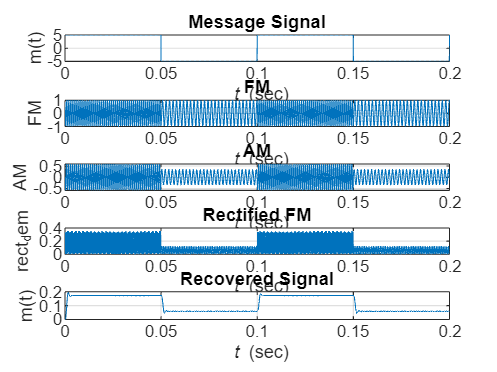

T = 0.2;
fs = 10000;
t = 0:1/fs:T;
Vm = 5;
fm = 10;
m = Vm*square(2*pi*fm*t);
fc = 200;
kf = 150;
m_int = (1/fs)*cumsum(m);
fm = cos(2*pi*fc*t + 2*pi*kf*m_int);
dem = diff(fm);
dem = [0,dem];
rect_dem = dem.^2;
wn = 0.1;
[b,a] = butter(4,wn);
rec = filter(b,a,rect_dem);
figure;
subplot(5,1,1);
plot(t,m);
title('Message Signal');
xlabel('{\it t} (sec)');
ylabel('m(t)');
grid;
subplot(5,1,2);
plot(t,fm);
title('FM');
xlabel('{\it t} (sec)');
ylabel('FM');
grid;
subplot(5,1,3);
plot(t,dem);
title('AM');
xlabel('{\it t} (sec)');
ylabel('AM');
grid;
subplot(5,1,4);
plot(t,rect_dem);
title('Rectified FM');
xlabel('{\it t} (sec)');
ylabel('rect_dem')
grid;
subplot(5,1,5);
plot(t,rec);
title('Recovered Signal');
xlabel('{\it t} (sec)');
ylabel('m(t)');
grid;

**Modulation and Demodulation of Triangular Wave using MATLAB Coding:**

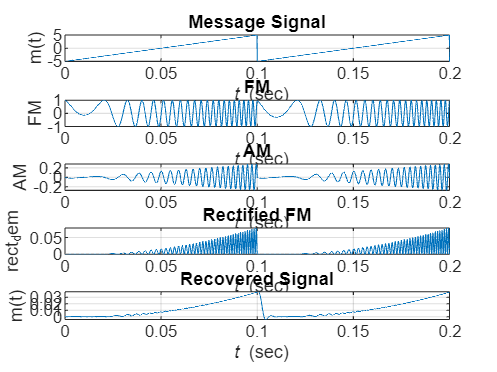

T = 0.2;
fs = 10000;
t = 0:1/fs:T;
Vm = 5;
fm = 10;
m = Vm*sawtooth(2*pi*fm*t);
fc = 200;
kf = 50;
m_int = (1/fs)*cumsum(m);
fm = cos(2*pi*fc*t + 2*pi*kf*m_int);
dem = diff(fm);
dem = [0,dem];
rect_dem = dem.^2;
wn = 0.04;
[b,a] = butter(4,wn);
rec = filter(b,a,rect_dem);
figure;
subplot(5,1,1);
plot(t,m);
title('Message Signal');
xlabel('{\it t} (sec)');
ylabel('m(t)');
grid;
subplot(5,1,2);
plot(t,fm);
title('FM');
xlabel('{\it t} (sec)');
ylabel('FM');
grid;
subplot(5,1,3);
plot(t,dem);
title('AM');
xlabel('{\it t} (sec)');
ylabel('AM');
grid;
subplot(5,1,4);
plot(t,rect_dem);
title('Rectified FM');
xlabel('{\it t} (sec)');
ylabel('rect_dem')
grid;
subplot(5,1,5);
plot(t,rec);
title('Recovered Signal');
xlabel('{\it t} (sec)');
ylabel('m(t)');
grid;